clear
clc
close all

% Loading in functions and generating the dataset
load("Data_Problem1_regression.mat");
Ts = [T1 T2 T3 T4 T5];
nums = [9; 8; 2; 2; 2]; % r0822921
Tnew = sum(Ts*nums,2)/(sum(nums));
dataset = [X1 X2 Tnew];


% Generating random training, validation, and test sets
indices = 1:13600;
full_ind = datasample(indices,3000,2,"Replace",false);

train_ind = full_ind(:,1:1000); 
test_ind = full_ind(:,1001:2000);
val_ind = full_ind(:,2001:3000);

full_set = dataset(full_ind, :);
train_set = dataset(train_ind, :);
val_set = dataset(val_ind, :);
test_set = dataset(test_ind, :);


% all dataset

full_X1 = full_set(:,1);
full_X2 = full_set(:,2);
full_T = full_set(:,3);


%training set
train_X1 = train_set(:,1);
train_X2 = train_set(:,2);
train_T = train_set(:,3);


% validation set

val_X1 = val_set(:,1);
val_X2 = val_set(:,2);
val_T = val_set(:,3);

% validation set

test_X1 = test_set(:,1);
test_X2 = test_set(:,2);
test_T = test_set(:,3);





% plot train set surface
xlin = linspace(min(dataset(:,1)), max(dataset(:,1)));
ylin = linspace(min(dataset(:,2)), max(dataset(:,2)));
[X,Y] = meshgrid(xlin,ylin);

f = scatteredInterpolant(train_X1,train_X2,train_T);
Z = f(X,Y);



figure
mesh(X,Y,Z)
axis tight; hold on
plot3(X,Y,Z,'.');




neurons = [20,40, 60, 80,100];
testMSE = zeros(5,5);
val_errors = zeros(5,5);
training_times = zeros(5,5);
max_run = 10
for i=1:length(neurons)
    value = neurons(i);
    value
    for j = 1:5
        j
        val_run_li = zeros(1,10)
        tic;
        for e=1:max_run
            layers(1,:) = round(value/j);
            
            
            % Building and training the network
            net = feedforwardnet(layers, 'trainlm');
    
            full_X = {full_X1';full_X2'};
    
        %   
    
    %         net = configure(net, train_X);
            net.trainParam.epochs = 1000;
        %         lm_net.trainParam.max_fail = 10;
            net.numInputs = 2;
            net.inputConnect(1,1) = 1;
            net.inputConnect(1,2) = 1;
            net.inputs{1}.size = 1;
            net.inputs{2}.size = 1;
    
            net.divideFcn = 'divideind';
            net.divideParam.trainInd = train_ind;
            net.divideParam.valInd = val_ind;
            net.divideParam.testInd = test_ind;
    
       
            net = configure(net,full_X);
            [net,tr] = train(net, full_X, full_T');
            validationMSE = tr.best_vperf;validationMSE
            val_run_li(e) = validationMSE

        end
        training_times(i, j) = toc/10;toc/10
        val_errors(i,j) = mean(val_run_li);
    end
end




% find the best architecture (neurons, layers)
[min_value, min_index] = min(val_errors(:));
[min_i, min_j] = ind2sub(size(val_errors), min_index);
min_i
min_j
best_neuron = neurons(min_i);best_neuron
best_layer = min_j;best_layer

val_errors(min_i,min_j)  



%build the best feedforward network 1:
layers = zeros(1, best_layer);
for i = 1:best_layer
    layers(i) = round(best_neuron/best_layer);
end

max_run = 10;
run_li = zeros(1,10);
predictions_li = zeros(10,1000);
for e=1:max_run
    net = feedforwardnet(layers, 'trainlm');
    
    
    full_X = {full_X1';full_X2'};
    net.trainParam.epochs = 1000;
    
    
    net.numInputs = 2;
    net.inputConnect(1,1) = 1;
    net.inputConnect(1,2) = 1;
    net.inputs{1}.size = 1;
    net.inputs{2}.size = 1;
    
    net.divideFcn = 'divideind';
    net.divideParam.trainInd = train_ind;
    net.divideParam.valInd = val_ind;
    net.divideParam.testInd = test_ind;
    
    net = configure(net,full_X);
    [net,tr] = train(net, full_X, full_T');
    testMSE = tr.best_tperf;testMSE
    run_li(e) = testMSE
    predictions = cell2mat(net({test_X1';test_X2'}));
    predictions_li(e,:) = predictions;

end 

testMSE = 0.0036

run_li =     0.0036         0         0         0         0         0         0         0         0         0


testMSE = 0.0087

run_li =     0.0036    0.0087         0         0         0         0         0         0         0         0


testMSE = 0.0049

run_li =     0.0036    0.0087    0.0049         0         0         0         0         0         0         0


testMSE = 0.0030

run_li =     0.0036    0.0087    0.0049    0.0030         0         0         0         0         0         0


testMSE = 0.0014

run_li =     0.0036    0.0087    0.0049    0.0030    0.0014         0         0         0         0         0


testMSE = 0.0012

run_li =     0.0036    0.0087    0.0049    0.0030    0.0014    0.0012         0         0         0         0


testMSE = 0.0019

run_li =     0.0036    0.0087    0.0049    0.0030    0.0014    0.0012    0.0019         0         0         0


testMSE = 0.0099

run_li =     0.0036    0.0087    0.0049    0.0030    0.0014    0.0012    0.0019    0.0099         0         0


testMSE = 0.0034

run_li =     0.0036    0.0087    0.0049    0.0030    0.0014    0.0012    0.0019    0.0099    0.0034         0


testMSE = 0.0032

run_li =     0.0036    0.0087    0.0049    0.0030    0.0014    0.0012    0.0019    0.0099    0.0034    0.0032


mean(run_li)

ans = 0.0041

columnAverages_predictions = mean(predictions_li, 1);
mse_error = (columnAverages_predictions'-test_T).^2

mse_error =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0011
    0.0000
    0.0000
    0.0000


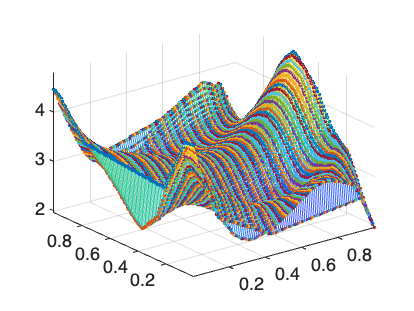


%Plotting the test set

xlin = linspace(min(dataset(:,1)), max(dataset(:,1)));
ylin = linspace(min(dataset(:,2)), max(dataset(:,2)));
[X,Y] = meshgrid(xlin,ylin);

f = scatteredInterpolant(test_X1,test_X2,test_T);
Z = f(X,Y);

figure
mesh(X,Y,Z)
axis tight; hold on
plot3(X,Y,Z,'.');

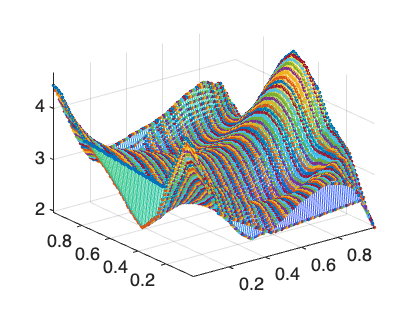



%Plotting the test prediction set

xlin = linspace(min(dataset(:,1)), max(dataset(:,1)));
ylin = linspace(min(dataset(:,2)), max(dataset(:,2)));
[X,Y] = meshgrid(xlin,ylin);

f = scatteredInterpolant(test_X1,test_X2,columnAverages_predictions');
Z = f(X,Y);

figure
mesh(X,Y,Z)
axis tight; hold on
plot3(X,Y,Z,'.');

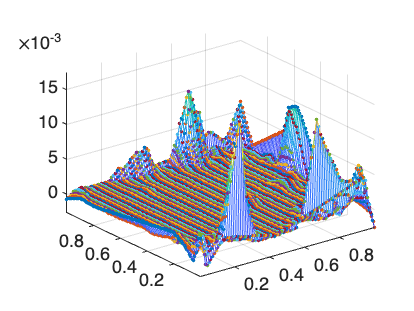


%Plotting the test error

xlin = linspace(min(dataset(:,1)), max(dataset(:,1)));
ylin = linspace(min(dataset(:,2)), max(dataset(:,2)));
[X,Y] = meshgrid(xlin,ylin);

f = scatteredInterpolant(test_X1,test_X2,mse_error);
Z = f(X,Y);

figure
mesh(X,Y,Z)
axis tight; hold on
plot3(X,Y,Z,'.');

% method 2:reset the proportion of train, val and test dataset

% early stop: the epochs are set to 1000, which is relatively large. From

% as the training, validation and test set are from 13600 data points,
% therefore, different sets will cause to different results and different
% best neural network. Therefore, every time of random selection, a new
% best neural network will be selected concerning the number of neurons and
% layers according to training and validation sets. 

% Different data results in different parameters; however, there is a rule
% that more neurons or more layers will not necessarily lead to better
% performance on validation set. For example, when one random selection is
% made in this report,  





























